# Quantum Key Distribution, BB84 Protocol

In this tutorial we will implement step by step the BB84 protocol for Quantum Key Distribution (QKD) [1]. The BB84 protocol utilizes qubits in order to grant the two parties, Alice and Bob, to share a secret key in a secure way, detecting eventual eavesdroppers (Eve).

first we define the number of qubits we want to send from Alice to Bob

n = 6; % requires n>0

Alice generates 2 random bitstrings of length n, $a$ and $b$, then se encodes them in n qubits.

Given qubit $k$ and $a_k$ and $b_k$, $|\psi_k \rangle$ will be encoded as:

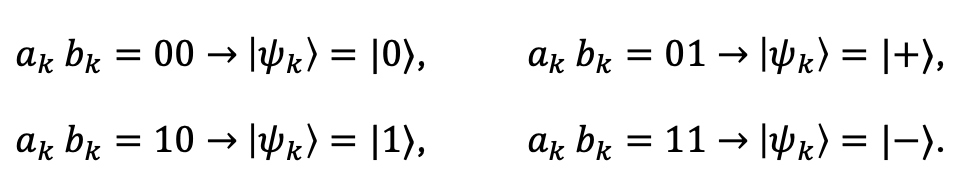

we can notice that, if $b_k =0$ she is encoding using the Z basis, while ff $b_k =1\;$she is encoding using the X Basis.

% generate alices bits
aliceBits = randi([0, 1], 1, n);
% generate alices bases
aliceBases = randi([0, 1], 1, n);

Alice now sends the encoded qubits over the channel to Bob

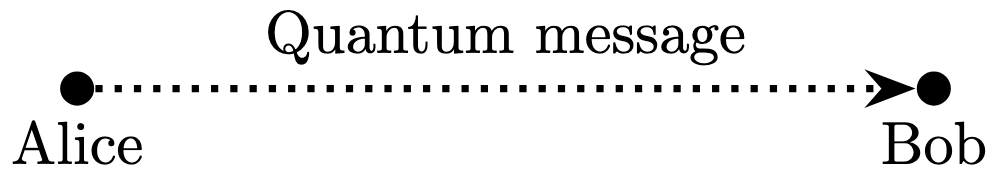

Bob generates his own string of basis $b^{\prime } =b_1^{\prime } b_2^{\prime } \cdots b_n^{\prime }$

% generate bob's bases
bobBases = randi([0, 1], 1, n);

% this function simulates the communication Alice --> Bob through a
% quantum channel
qc = quantumChannelCommunication(n, aliceBits, aliceBases, bobBases);

Now Bob will measure the qubits according to his basis and based on the results of this measurments he will generate his own bitstring $a^{\prime }$

% Bob measures the results with his randomly chosen basis
s = simulate(qc);
M = randsample(s, 1);
bobResults = zeros(1, n);
measuredString = M.MeasuredStates{1};

for i = 1:n
    if measuredString(i) == '0'
            bobResults(i) = 0;
    else
        bobResults(i) = 1;
    end
end

fprintf('Bob mesured state:\n%s\n', measuredString);

Bob mesured state:
010010


fprintf('Alice bits:')

Alice bits:

fprintf('%d', aliceBits);

010000

At this point both Alice and Bob have thw bitstrings, they both communicate to eachother $b$ and $b^{\prime }$, when $b_k ={b_k }^{\prime }$htey keep the bits $a_k$ and ${a_k }^{\prime }$ otherwise they discard them.

% this function simulates the communication Alice <--> Bob through a
% public classical channel
sameBaseIndices = classicalChannelCommunication(aliceBases, bobBases);

% get the resulting raw-key
[aliceRawKey, bobRawKey] = calculateRawKey(sameBaseIndices, aliceBits, bobResults);

Due to the no cloning theorem no evesdropper can clone the qubits sent by Alice in the quantum channel [2].

An evesdropper could only measure the qubits, but he does not know the correct basis of measurement, this could also potentialy disturb the qubits.

When Alice and Bob share the bitstrings, if the eavesdropper’s basis is different from Alice’s basis, and Bob’s basis is the same as Alice’s basis, Alice and Bob can detect the existence of the eavesdropper.

This happends with probability $\frac{1}{4}$ meaning that the probability of succefull detection decomes almost certain if $n>24$

% error estimate to detect eavesdropper 
% eavesdropper simulation still to be implemented
mismatchCount = sum(aliceRawKey ~= bobRawKey);
qber = mismatchCount / length(aliceRawKey);
fprintf('error rate = %.2f%%\n', qber * 100);

error rate = 0.00%


% if error rate < 0.15 then ok
% else discard key
if qber > 0.15
    disp('communication likely intercepted!');

finally, Alice and Bob can build their key based on the $a_k$ and ${a_k }^{\prime }$ corrisponding to the $b_k$ and ${b_k }^{\prime }$ they share

else
    validIndices = (aliceRawKey == bobRawKey);
    finalKey = aliceRawKey(validIndices);
    fprintf('raw-key, %d bit(s): ', length(finalKey));
    fprintf('%d', finalKey);
end

raw-key, 4 bit(s): 

0000

% HELPER FUNCTIONS
function qc = quantumChannelCommunication(n, aliceBits, aliceBases, bobBases)
    gates = [];
    
    % create alices bits 
    for i = 1:n
        if aliceBits(i) == 1
            gates = [gates, xGate(i)];
        end
    end

    % create alices bases
    for i = 1:n
        if aliceBases(i) == 1
            gates = [gates, hGate(i)];
        end
    end

    % create bobs bases
    for i = 1:n
        if bobBases(i) == 1
            gates = [gates, hGate(i)];
        end
    end

    qc = quantumCircuit(gates, n);
end

function sameBaseIndices = classicalChannelCommunication(aliceBases, bobBases)
    sameBaseIndices = find(aliceBases == bobBases);
end

function [aliceRawKey, bobRawKey] = calculateRawKey(sameBaseIndices, aliceBits, bobResults)
    aliceRawKey = aliceBits(sameBaseIndices);
    bobRawKey   = bobResults(sameBaseIndices);
end

## Refernces

[1] C. H. Bennett, G. Brassard, “Quantum Cryptography: Public key distribution and coin tossing”

[2] W. K. Wootters,  W. H. Zurek, “A single quantum cannot be cloned”